## Tópicos especiais em Estatística Aplicada - 2023/2

## EPC3

## Aluno: João Gabriel Santos Custodio

1) A função densidade de probabilidade do comprimento de uma barra de metal é dada por f(x) = 2 para 2.3 < x < 2.8 m.

1.1. Se as especificações para produzir esta barra forem comprimento de 2.25 a 2.75 m, qual a proporção de barras que não atenderá as especificações?

Para o intervalo de 2.75<x<2.8 as barras não atenderão as especificações. A proporção de barras que não atenderão as especificações pode ser encontrada sendo a área sob a curva desse intervalo de probabilidade.

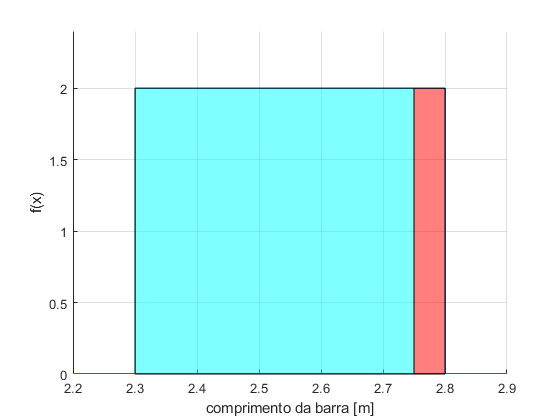

x = linspace(2.2, 2.9, 700);
prob = 2;
figure;
grid(), hold on;
y1 = cat(2, cat(2, zeros(1,100), ones(1,500)*prob), zeros(1,100));
stairs(x, y1)
ylim([0, 1.2*prob])
area([2.3, 2.75], [2, 2], 'FaceColor', 'cyan', 'FaceAlpha', 0.5);
area([2.75, 2.8], [2, 2], 'FaceColor', 'red', 'FaceAlpha', 0.5);
ylabel("f(x)")
xlabel("comprimento da barra [m]")

Portanto, evidencia-se que a área sob o gráfico onde não atende as especificações é a área destacada em vermelho no gráfico acima. Dessa forma, temos:

(2.8-2.75)*2 = 0.05*2 = 0.10 = 10%. 

Logo 10% das barras produzidas não atenderão as espeficicações.

1.2. Suponha que a função densidade de probabilidade seja f(x) = 2 para o intervalo de 0.5 m de comprimento. Sobre qual valor deveria f(x) ser centrada para obter a máxima proporção de barras dentro da especificação?

Utilizando o intervalo de 0.5m de comprimento, basta centralizar f(x) no centro do intervalo especificado no item 1.1 e encontrar a mediana. Nesse caso, como já mencionado, o intervalo é de 2.3<x<2.75.

x1_2 = linspace(2.3, 2.75, 1000);
median(x1_2)

ans = 2.5250

Conclui-se, portanto, que para nenhuma barra ser produzida fora do intervalo especificado, f(x) há de ser centrada no valor 2.53.

2. O volume de enchimento de uma máquina de enchimento automatizada usada para encher refrigerantes é normalmente distribuído com uma média de 360ml e um desvio padrão de 5ml.

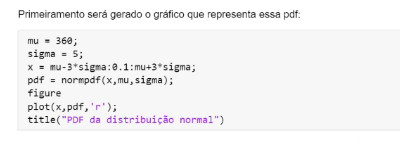

media = 360; % 360ml de média de enchimento normalmente distribuidos
sigma = 5; % 5ml de desvio padrão
x = media - 3*sigma: 0.1: media+3*sigma;
pdf = normpdf(x, media, sigma);

'normpdf' requires Statistics and Machine Learning Toolbox.

figure
plot(x, pdf, 'blue')
title("PDF")

Abaixo temos o gráfico que mostra a PDF do problema:

2.1 Qual a probabilidade de que o volume seja menor que 355ml?

2.2 Se os refrigerantes com menos de 350ml e mais de 370ml forem eliminados, qual a proporção de refrigerantes eliminados?

2.3 Determine as especificações de volume de modo que 99% dos refrigerantes sejam aceitos.

3. Seja uma variável aleatória X com distribuição binomial. Escolha um valor de n > 10 e p conforme abaixo.

3.1 Escolha p tal que X possa ser aproximada por uma variável aleatória Y com distribuição normal, plotando os gráficos da distribuição de X e de Y.

3.2 Repita para p tal que esta aproximação não seja possível, mostrando isso através dos gráficos de distribuição correspondentes.

4. Gere uma variável aleatória X com distribuição normal padronizada contendo 500 amostras.

4.1 Faça um histograma de X e sobre ele plote a pdf (0,1)

4.2 Faça um histograma de Y = X² e sobre ele plote a pdf 

4.3 Obtenha P(−2 ≤ X ≤ 2) e y tal que P(Y ≤ y) = P(−2 ≤ X ≤ 2)

4.4 Plote a pdf χn2 para n = 1,2, . . ,10, explique o efeito de n sobre a pdf, e para n = 10 compare χn 2 com א(n, √2n).

5. Selecione aleatoriamente 20 amostras de X e construa o intervalo de confiança para a média com

α = 5% . 

Considere a variância conhecida, obtida da população de 1000 amostras. Repita este procedimento e construa 50 intervalos para a média. Plote os intervalos das médias junto com a média de X e comente os resultados que obteve, comparando os intervalos estimados e verificando se eles contêm a média conhecida da população.

6. Plote o histograma cumulativo das 50 médias calculadas e compare com a cdf teórica da média amostral de X.

7. Repita a atividade 5 fazendo um intervalo de confiança para a variância da variável X gerada com distribuição normal, média μ e variância σ escolhidas. Faça o histograma das 50 variâncias e analise.

8. Um fabricante de equipamentos seleciona aleatoriamente 1000 unidades e verifica que 5 têm defeito.

8.1. Construa um intervalo de confiança de 95% para a proporção de unidades com defeito.

8.2. Há evidências para suportar a afirmação de que a fração de peças com defeito é menor que 1%?